close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
ht = sqrt(g * mass / (Kt * 4));


n_inputs = 4;			% number of inputs
n_states = 4;			% number of states 4 (vectors)
state_dim = 3;			% dimension of each state

## OG Controller sim

max_time = 10;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
V_hist = zeros(n_samples);
dV_hist = zeros(n_samples);

% extracts qr from a reference
qr_ext = [0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial conditions
% Currently set up to show the quad being far from the reference in every
% direction (-theta and -omegax for maximum testage)
r_r = [0; 0; 0];
% r_hist(3, 1) = 1;
% q_hist(1, 1) = -0.17;
% q_hist(3, 1) = -0.6 * pi;
omega_hist(1, 1) = 0.0;
omega_hist(2, 1) = 0.01;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib);

	% update control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = Rufous_og_controller(Kt, mass, g, q_hist(:,i), 75, 100, 0.08, 0.5, 15);
	Katt = Kfb(:, 7:9);

	% update states
	u_hist(:, i + 1) = Kff + (Kfb * Kref * (R - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = wrap_angle(q_hist(:, i) + (dq * dt));
	qr_hist(:, i + 1) = -qr_ext * (Kref * (R - X));
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	% Sample Lyapunov
	V = Rufous_Lyapunov(q_hist(1, i+1), q_hist(2, i+1), q_hist(3, i+1), omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), qr_hist(:, i+1), Ib, Katt);
	dV = Rufous_Lyapunov_dot(q_hist(1, i+1), q_hist(2, i+1), q_hist(3, i+1), omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), do(1), do(2), do(3), Ib, Katt);
	V_hist(i) = V;
	dV_hist(i) = dV;
	if V > 1e12 || dV > 1e12 % instability catcher, sorta works, not the way it should though (use Vdot instead)
		fprintf("Breaking for Lyapunov value %d at %i", V, i);
		fprintf("Breaking for dLyapunov value %d at %i", dV, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

figure
title("Position history")
position_titles = ["X Postion" "Y Position" "Z Position" "X Velocity" "Y Velocity" "Z Velocity"];
plot_vectors(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, position_titles, 5);

figure
title("Attitude history")
attitude_titles = ["X Attitude" "Y Attitude" "Z Attitude" "X Angular Rate" "Y Angular Rate" "Z Angular Rate"];
plot_vectors(t_space, q_hist, omega_hist, qr_hist, attitude_titles, 1);

figure
plot(t_space, V_hist)
title("V(x)")

figure
plot(t_space, dV_hist)
title("dV(x)")

## NL Controller sim

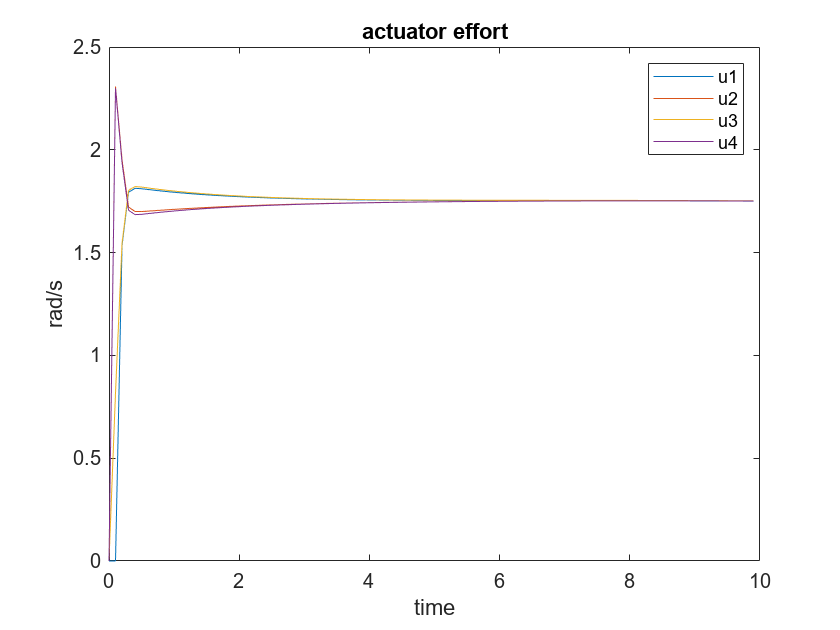

max_time = 10;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
V_hist = zeros(n_samples);
dV_hist = zeros(n_samples);

% extracts qr from a reference
qr_ext = [0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial conditions
% Currently set up to show the quad being far from the reference in every
% direction (-theta and -omegax for maximum testage)
r_r = [0; 0; 10];
r_hist(3, 1) = 1;
q_hist(1, 1) = -0.17;
q_hist(3, 1) = -0.6 * pi;
omega_hist(1, 1) = 0.0;
omega_hist(2, 1) = 0.01;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib);

	% update control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = Rufous_nl_controller(Kt, mass, g, [0; 0; 0], 60, 100, 0.01, 0.01, 1, 20);
	Katt = Kfb(:, 7:9);

	% update states
	u_hist(:, i + 1) = Kff + (Kfb * Kref * (R - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = wrap_angle(q_hist(:, i) + (dq * dt));
	qr_hist(:, i + 1) = qr_ext * (Kref * (R - X));
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	% Sample Lyapunov
	V = Rufous_Lyapunov(q_hist(1, i+1), q_hist(2, i+1), q_hist(3, i+1), omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), qr_hist(:, i+1), Ib, Katt);
	dV = Rufous_Lyapunov_dot(q_hist(1, i+1), q_hist(2, i+1), q_hist(3, i+1), omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), do(1), do(2), do(3), Ib, Katt);
	V_hist(i) = V;
	dV_hist(i) = dV;
	if V > 1e12 || dV > 1e12 % instability catcher, sorta works, not the way it should though (use Vdot instead)
		fprintf("Breaking for Lyapunov value %d at %i", V, i);
		fprintf("Breaking for dLyapunov value %d at %i", dV, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

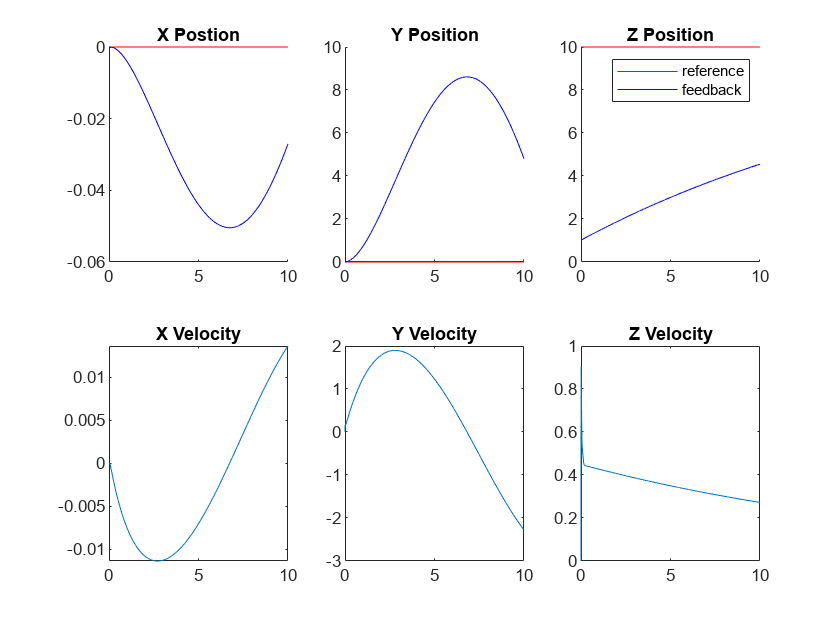


figure
title("Position history")
position_titles = ["X Postion" "Y Position" "Z Position" "X Velocity" "Y Velocity" "Z Velocity"];
plot_vectors(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, position_titles, 5);

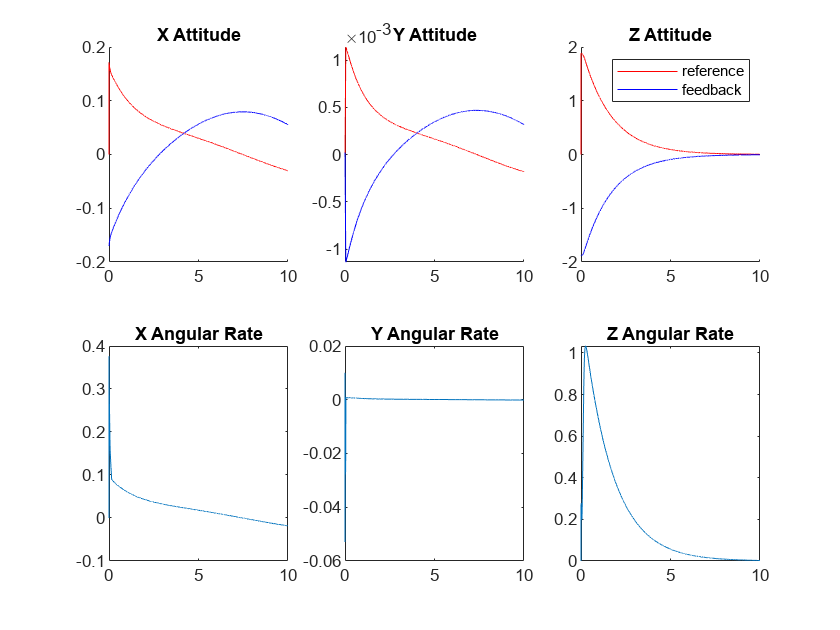


figure
title("Attitude history")
attitude_titles = ["X Attitude" "Y Attitude" "Z Attitude" "X Angular Rate" "Y Angular Rate" "Z Angular Rate"];
plot_vectors(t_space, q_hist, omega_hist, qr_hist, attitude_titles, 1);

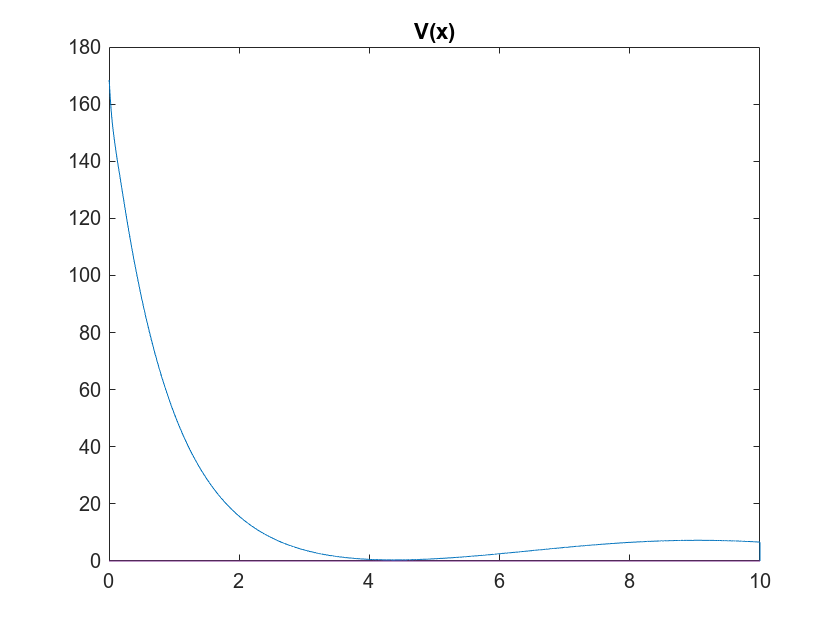


figure
plot(t_space, V_hist)
title("V(x)")


figure
plot(t_space, dV_hist)
title("dV(x)")